varTypes = {'int8','string','double','double'};
varNames = {'No','condition','Threshold','slope'};
sz = [64 size(varTypes,2)];
H = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

width = 17.2666

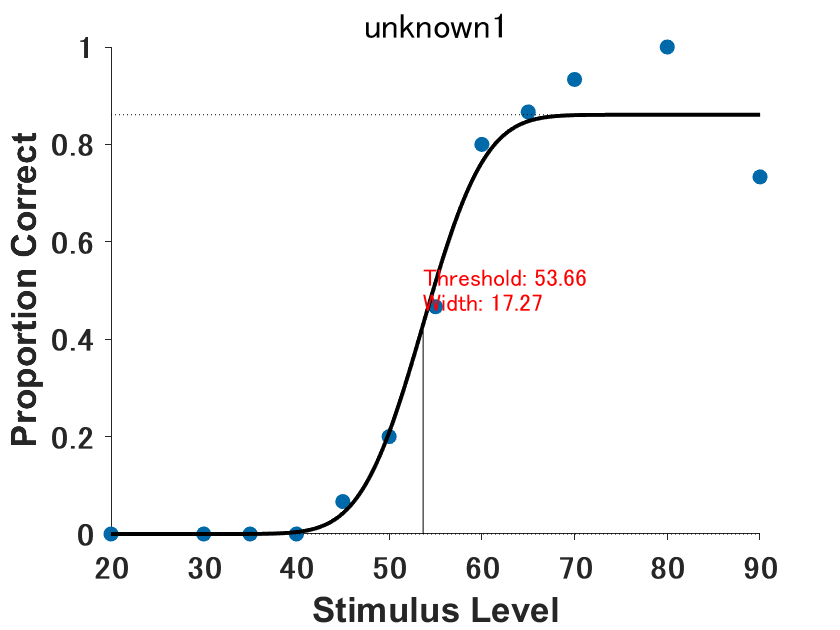

width = 13.8464

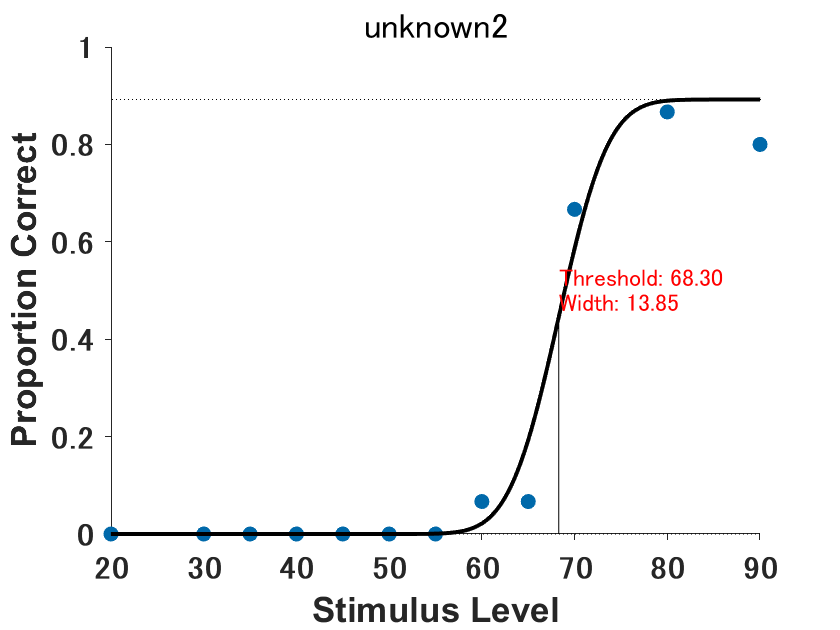

width = 9.8008

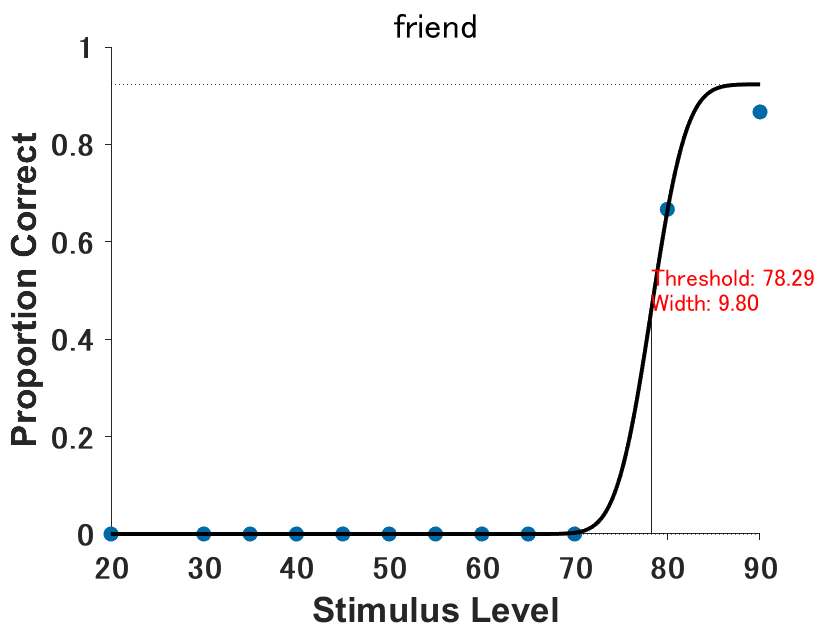

H = 279×5 table
    No    condition    Threshold    slope    Width
    __    _________    _________    _____    _____

    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  
    0     <missing>        0          0        0  


for j =70:70
    
no = j;
filePath = "C:\顔認知_実験\20240627_test\Metrics\eachCsv\" + num2str(no) + "_each.csv";
% ファイルの存在確認
if exist(filePath, 'file')
    % ファイルを読み込む
    T = readtable(filePath);
else
    error("ファイルが見つかりません: " + filePath);
end

conditions = ["u1","u2","f"];
j_conditions = ["unknown1","unknown2","friend"];
keySet = {0,10,20,30,35,40,45,50,55,60,65,70,80,90,100};
valueSet = 1:15;
M = containers.Map(keySet,valueSet);
varTypes = {'int8','int8','int8'};
varNames = {'u1','u2','f'};
sz = [15 size(varTypes,2)];

C = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);
for i = 1:675
    if T{i,"judge"} == 1
        C{M(T{i,"percent"}),T{i,"condition"}} = C{M(T{i,"percent"}),T{i,"condition"}} + 1;
    end
end
C;

Threshold = zeros(4,2);
for i = 1:3
    D = C{:,conditions(i)};
    data = zeros(15,3);
    data(:,1) = [0;10;20;30;35;40;45;50;55;60;65;70;80;90;100];
    data(:,2) = D;
    data(:,3) = 15;
    
    options             = struct;
    options.sigmoidName = 'norm';
    options.expType     = 'YesNo';
    options.confP = .80;
    result = psignifit(data,options);
    
    result.Fit;
    
    figure
    plotPsych(result);
    title(j_conditions(i))

    %xlabel('Stimulus (self%)'); % 设置横坐标标签
    %ylabel('Threshold');        % 设置纵坐标标签

     % 计算50%正确判断的阈值
    threshold = result.Fit(1); 

    % 计算宽度
    width = result.Fit(2)
    
    
    resultSmall = rmfield(result,{'Posterior','weight'});
    
    slope = getSlope(result, result.Fit(1));
    Threshold(i,:) = [result.Fit(1) slope];
    H{(no-1)*4+i,"No"} = no;
    H{(no-1)*4+i,"condition"} = conditions(i);
    H{(no-1)*4+i,"Threshold"} = result.Fit(1);
    H{(no-1)*4+i,"Width"} = width;
    H{(no-1)*4+i,"slope"} = slope;
    xlim([20 90]); % 设置X轴的显示范围为从0到100
    xticks(0:10:100); % 设置X轴的刻度间隔为10
    yticks(0:0.2:1); % 设置X轴的刻度间隔为10

    xlabel.FontSize = 24; % 设置X轴标签的字号为12
    ylabel.FontSize = 24; % 设置Y轴标签的字号为12


    % 设置坐标轴刻度标签的粗细
    ax = gca; % 获取当前坐标轴的句柄
    ax.FontWeight = 'bold'; % 加粗坐标轴刻度标签
    ax.FontSize = 16; % 设置坐标轴刻度标签的字号为10
    
    textX = result.Fit(1); % 假设x坐标为Threshold的值
    textY = 0.5; % 假设y坐标为图形的中间位置
    text(textX, textY, sprintf('Threshold: %.2f\nWidth: %.2f', threshold, width), 'FontSize', 12, 'Color', 'red');
    
    
    % 保存するディレクトリの絶対パス
    saveDir = "C:\顔認知_実験\20240627_test\Metrics\raw\psychometric_function\";
    % 画像を保存
saveas(gcf, saveDir + num2str(no) + "_" + conditions(i) + "_raw2.png");
    
end
H
end

% 保存するディレクトリの絶対パス
saveDir = "C:\顔認知_実験\20240627_test\Metrics\raw\";
% ファイルの絶対パス
filePath = saveDir + "psychometric_raw.csv";
% ディレクトリが存在するか確認し、存在しない場合は作成
if ~exist(saveDir, 'dir')
    mkdir(saveDir);
end
% テーブルを書き込む
writetable(H, filePath);

writetable(H,"Metrics/raw/psychometric_raw.csv")

ファイル 'Metrics/raw/psychometric_raw.csv' を書き込み用に開けません:

No such file or directory